**WHEELS DISPLACEMENT**

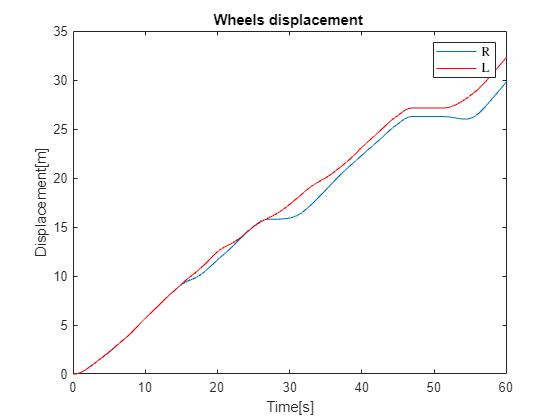

clear
load('Encoder_Data.mat')
Tf = length(R_acu(:,1))*Ts;
t = R_acu(:,1);
figure;
plot(L_acu(:, 1), L_acu(:,2));
hold on;
plot(R_acu(:, 1), R_acu(:,2), 'r')
xlim([0, Tf])
xlabel('Time[s]')
ylabel('Displacement[m]')
title('Wheels displacement ')
legend ('R','L','Interpreter','latex','Fontsize',10)

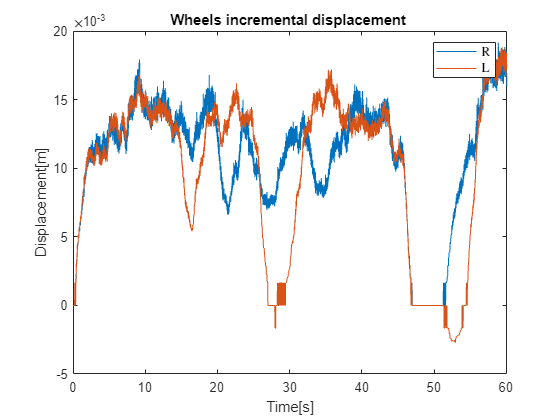

v = linspace(0,Ts);
figure
plot(t(1:end-1), diff(R_acu(:,2)))
hold on 
plot(t(1:end-1), diff(L_acu(:,2)))
%plot(diff(R_acu(:,2)))%entre ans para la velocidad
xlim([0 Tf])
xlabel('Time[s]')
ylabel('Displacement[m]')
title('Wheels incremental displacement ')
legend ('R','L','Interpreter','latex','Fontsize',10)

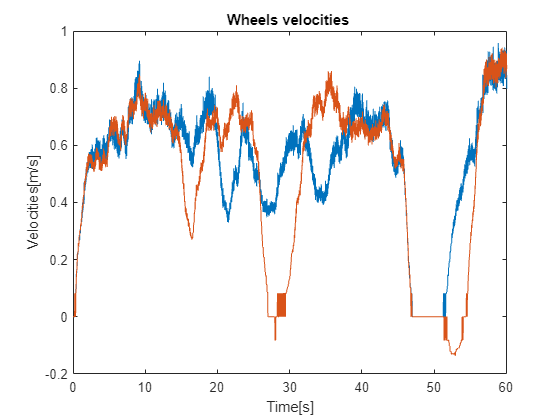

figure
plot(t(1:end-1), diff(R_acu(:,2))/Ts)
hold on 
plot(t(1:end-1), diff(L_acu(:,2))/Ts)
xlim([0 Tf])
xlabel('Time[s]')
ylabel('Velocities[m/s]')
title('Wheels velocities ')

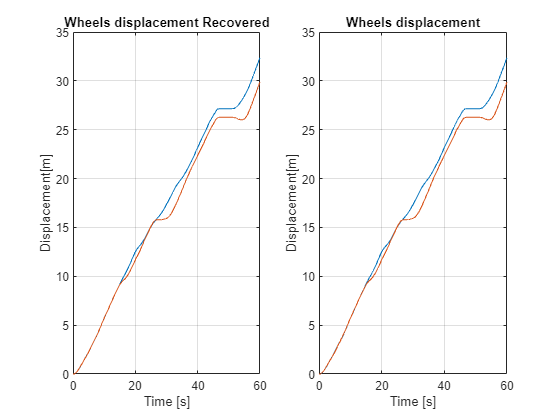

R_ac = cumsum(diff(R_acu(:, 2)),1);
L_ac = cumsum(diff(L_acu(:,2)),1);
figure
subplot(1,2,1)
plot(t(1:end-1), R_ac)
hold on
plot(t(1:end-1), L_ac)
xlim([0 Tf])
grid on
title('Wheels displacement Recovered')
xlabel('Time [s]')
ylabel('Displacement[m]')

subplot(1,2,2)
plot(t, R_acu(:,2))
hold on
plot(t, L_acu(:,2))
xlim([0 Tf])
grid on
title('Wheels displacement')
xlabel('Time [s]')
ylabel('Displacement[m]')

R_diff = diff(R_acu(:,2));
L_diff = diff(L_acu(:,2));

delta_d=(R_inc+L_inc)/2

Unrecognized function or variable 'R_inc'.

delta_t=(R_inc-L_inc)/W

Initial_pose=transl(8.65,17.2,0)*trotz(-pi/2)
Pose(:,:,1)=Initial_pose;
 for i=1:length(t)-1
    Pose(:,:,i+1)=Pose(:,:,i)*transl(delta_d(i),0,0)*trotz(delta_t(i));
    %Pose(:,:,i+1)=Pose(:,:,i)*trotz(delta_t(i))*transl(delta_d(i),0,0);
    Position(:,i+1)=transl(Pose(:,:,i));
    Orientation(:,i+1)=tr2rpy(Pose(:,:,i));
 end

 Initial_position=transl(Initial_pose)
 Initial_orientation=-pi/2;
 x(1)=Initial_position(1)+0.05; %Mas 0.05 para que se vea la diferencia de la trayectoria aunque sea igual
 y(1)=Initial_position(2);
 o(1)=Initial_orientation;
  for i=1:(length(t)-1)
    x(i+1)= x(i)+delta_d(i)*cos(o(i));
    y(i+1)= y(i)+delta_d(i)*sin(o(i));
    o(i+1)=o(i)+delta_t(i);
  end

 figure
plot(Position(1,2:end),Position(2,2:end))
grid on
hold on
title('Trajectory')
xlabel ('X [m]')
ylabel ('Y [m]')
plot(x,y)
figure
plot(t,o,'r')
hold on
plot(t,mod(o,2*pi),'b')
figure
I=imread('Enviroment.png');
xI=[0 35.9];
yI=[23.31 0];
image(I,'XData',xI,'YData',yI);
axis xy
hold on
plot(Position(1,2:end),Position(2,2:end))
delta_d_n=((R_inc+L_inc)/2)+randn((length(t)-1),1)*0.005;
 delta_t_n=((R_inc-L_inc)/W)+randn((length(t)-1),1)*0.005;

 figure
hold on
plot(t(1:end-1),delta_d_n,'r')
xlim ([0 Tf])
grid on
title('Odometry displacement with noise')
xlabel ('t [s]')
ylabel ('\delta_d [m]')
plot(t(1:end-1),delta_d,'b')
figure
hold on
plot(t(1:end-1),delta_t_n,'r')
xlim ([0 Tf])
grid on
title('Odometry change of orientation with noise')
xlabel ('t [s]')
ylabel ('\delta_o [m]')
plot(t(1:end-1),delta_t,'b')
Initial_pose=transl(8.65,17.2,0)*trotz(-pi/2);
Pose_n(:,:,1)=Initial_pose;
 for i=1:length(t)-1
    Pose_n(:,:,i+1)=Pose_n(:,:,i)*transl(delta_d_n(i),0,0)*trotz(delta_t_n(i));
    Position_n(:,i+1)=transl(Pose_n(:,:,i));
    Orientation_n(:,i+1)=tr2rpy(Pose_n(:,:,i));
 end
 plot(Position_n(1,2:end),Position_n(2,2:end),'r')
 hold on
 plot(Position(1,2:end),Position_n(2,2:end),'b')
Initial_pose=transl(8.65,17.2,0)*trotz(-pi/2)

Pose_n(:,:,1)=Initial_pose;
for j=1:1000
delta_d_n=((R_inc+L_inc)/2)+randn((length(t)-1),1)*0.005; %Dices again
delta_t_n=((R_inc-L_inc)/W)+randn((length(t)-1),1)*0.005; 
 for i=1:length(t)-1
    Pose_n(:,:,i+1)=Pose_n(:,:,i)*transl(delta_d_n(i),0,0)*trotz(delta_t_n(i));
    Position_n(:,i+1)=transl(Pose_n(:,:,i));
    Orientation_n(:,i+1)=tr2rpy(Pose_n(:,:,i));
 end
 Positions_n(:,j)=Position_n(:,end);
 Orientations_n(:,j)=Orientation_n(:,end);
end
figure
scatter(Positions_n(1,:),Positions_n(2,:))